# Record_demo

## Construction of `Record` objects

The simplest way is to specify the file path of a `.mat` file as the single input argument.

`obj = Record(matfilepath)`

`% matfilename    Char type single input. Accepts a valid file path `

`%                 (char type) of a .mat file that contains Spike2`

`%                generated structures of electrophysiological `

`%                recordings`

dirpath1 = fileparts(which('WaveformChan.m'));

matname1 = 'kjx127a01@0-20_double.mat';

matfilepath = fullfile(dirpath1, matname1);

rec1 = Record(matfilepath);
disp(rec1)

  Record with properties:

    RecordTitle: 'kjx127a01@0-20_double.mat'
          Chans: {5×1 cell}
           Time: [340000×1 double]
         Length: 340000
      SInterval: 5.8824e-05
        MaxTime: 19.9999
       Duration: 19.9999
     ChanTitles: {5×1 cell}
          Start: 0
          SRate: 17000



rec1.chantitles

ans = 5×1 cell array
    {'onset'    }
    {'LTS'      }
    {'LTSmk'    }
    {'probeA07e'}
    {'EEG'      }


rec1.Chans

ans = 5×1 cell array
    {1×1 EventChan   }
    {1×1 EventChan   }
    {1×1 EventChan   }
    {1×1 EventChan   }
    {1×1 WaveformChan}

ans = struct with fields:
    chantitles: {5×1 cell}
           fig: [1×1 Figure]
            ax: [5×1 Axes]
         lineh: {5×1 cell}

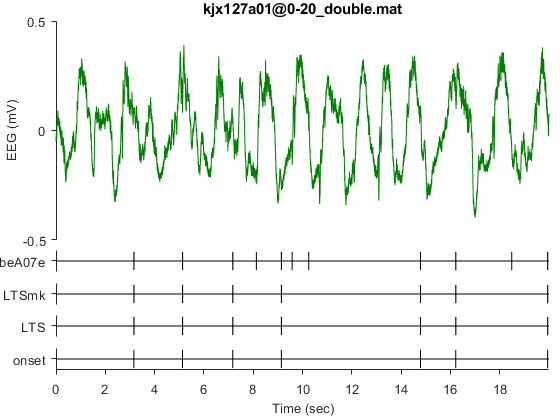


rec1.plot

You can delete a Chan object or more from a Record

rec2 = rec1.removechan('LTSmk');
rec2.chantitles

ans =     'onset'
    'LTS'
    'probeA07e'
    'EEG'



rec3 = rec1.removechan({'LTSmk', 'onset'});
rec3.chantitles

ans =     'LTS'
    'probeA07e'
    'EEG'
